# Solution to the *Population Models I* exercise

The file `population.xlsx` contains the estimated world population (in thousands) every other year from 1950 to 2014.

## 1. Read and plot data

Import the world population data in `population.xlsx` as a table. Plot the data as a function of year with circular markers.

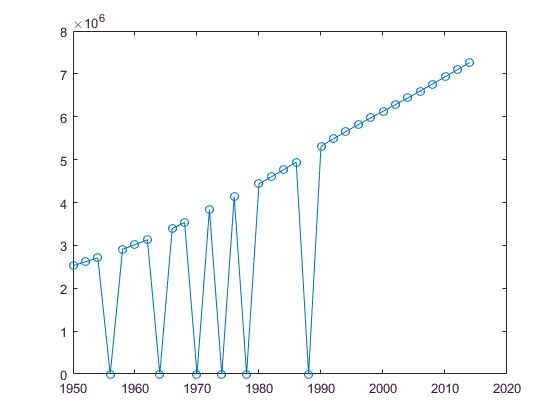

pop = readtable('C:\class\coursefiles\mlbe\exercises\population.xlsx');
plot(pop.Year,pop.Population,'o-')

## 2. Replace incorrect values with NaN

Note that a population value of 0 is clearly a missing value. Replace the zeros with `NaN`. Replot the result.

pop = standardizeMissing(pop,0)

pop =     Year    Population
    ____    __________

    1950    2.5251e+06
    1952    2.6179e+06
    1954    2.7107e+06
    1956           NaN
    1958    2.9097e+06
    1960    3.0183e+06
    1962    3.1336e+06
    1964           NaN
    1966    3.3907e+06
    1968     3.534e+06
    1970           NaN
    1972    3.8336e+06
    1974           NaN
    1976    4.1365e+06
    1978           NaN
    1980    4.4396e+06
    1982     4.599e+06
    1984    4.7657e+06
    1986    4.9421e+06
    1988           NaN
    1990    5.3097e+06
    1992    5.4851e+06
    1994    5.6533e+06
    1996    5.8154e+06
    1998    5.9719e+06
    2000    6.1266e+06
    2002    6.2823e+06
    2004    6.4398e+06
    2006    6.6002e+06
    2008    6.7637e+06
    2010    6.9297e+06
    2012    7.0975e+06
    2014    7.2658e+06


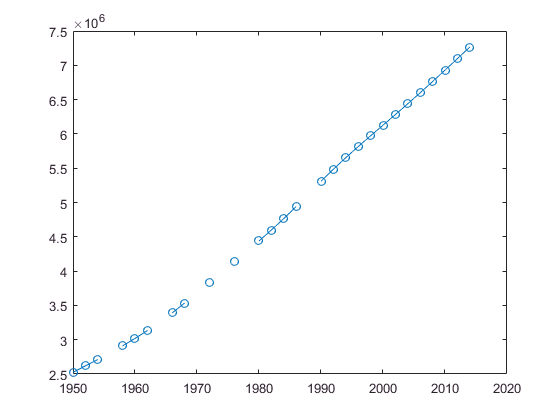

plot(pop.Year,pop.Population,'o-')

## 3. Fill missing values

Use `fillmissing` to replace the missing values with linearly interpolated values. Replot the result.

pop = fillmissing(pop,'linear')

pop =     Year    Population
    ____    __________

    1950    2.5251e+06
    1952    2.6179e+06
    1954    2.7107e+06
    1956    2.8102e+06
    1958    2.9097e+06
    1960    3.0183e+06
    1962    3.1336e+06
    1964    3.2621e+06
    1966    3.3907e+06
    1968     3.534e+06
    1970    3.6838e+06
    1972    3.8336e+06
    1974    3.9851e+06
    1976    4.1365e+06
    1978    4.2881e+06
    1980    4.4396e+06
    1982     4.599e+06
    1984    4.7657e+06
    1986    4.9421e+06
    1988    5.1259e+06
    1990    5.3097e+06
    1992    5.4851e+06
    1994    5.6533e+06
    1996    5.8154e+06
    1998    5.9719e+06
    2000    6.1266e+06
    2002    6.2823e+06
    2004    6.4398e+06
    2006    6.6002e+06
    2008    6.7637e+06
    2010    6.9297e+06
    2012    7.0975e+06
    2014    7.2658e+06


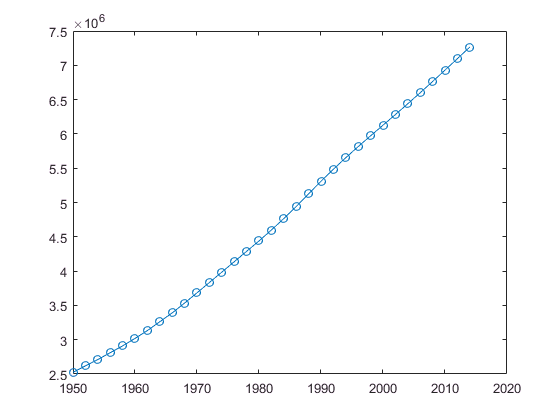

plot(pop.Year,pop.Population,'o-')

## 4. Fit linear model to the data

Create a column vector of years from 1950 to 2050.

y = (1950:2050)';

Fit a linear model to the data. Evaluate this model at each year from 1950 to 2050. Add the result to the plot of the data.

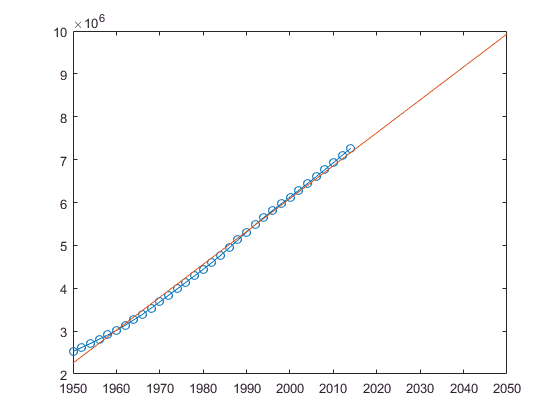

c = polyfit(pop.Year,pop.Population,1);
hold on
plot(y,polyval(c,y))
hold off

## 5. Fit polynomial models of degrees 2 - 5

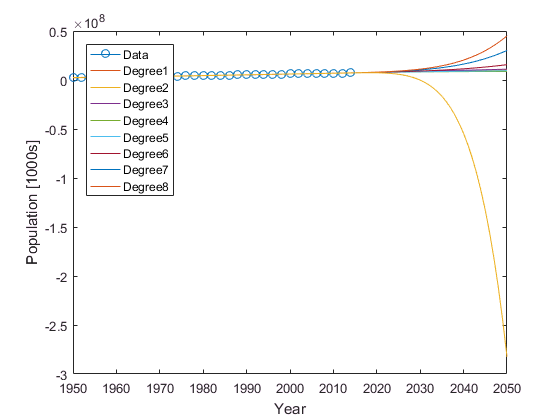

hold on

leg{1}=['Data'];

for polyN = 1 : 8
    
    [c,~,mu] = polyfit(pop.Year,pop.Population,polyN);
    plot(y,polyval(c,y,[],mu))
    
    leg{polyN+1} = ['Degree', num2str(polyN)];

end
hold off

xlabel('Year')
ylabel('Population [1000s]')
legend(leg,'location','nw')

%legend('Data','Degree 1','Degree 2','Degree 3','Degree 4','Degree 5',...
%    'Location','northwest')